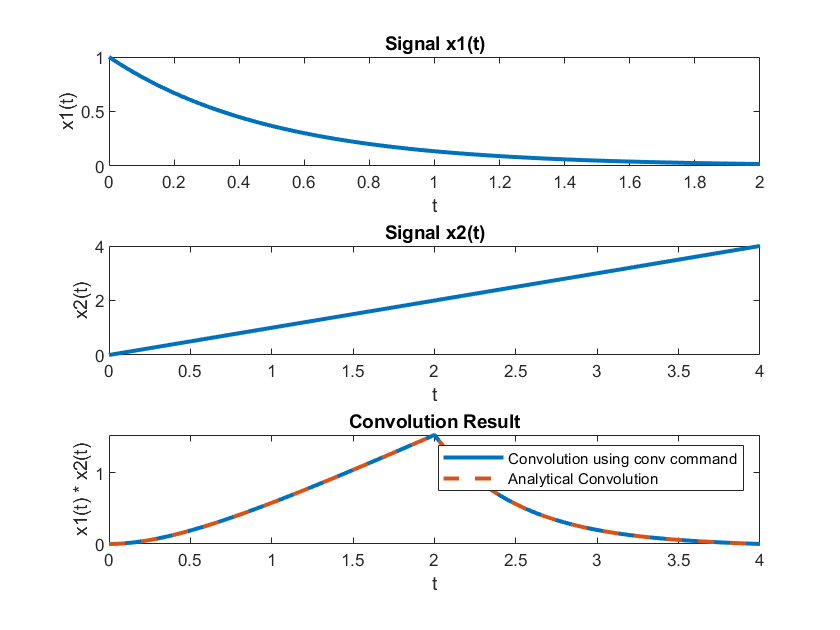

% We Define the signals x1(t) and x2(t)
t1 = 0:0.01:2;
x1 = exp(-2*t1);  % Signal 1: Exponential decay

t2 = 0:0.02:4;   % Different time interval for signal 2
x2 = t2;          % Signal 2: Linear ramp

% Convolve the signals in the time domain
dt1 = t1(2) - t1(1);
dt2 = t2(2) - t2(1);
t_conv = conv(x1, x2) * dt1;  % Convolution result in time domain with different time intervals

% Analytical convolution of the signals
t_conv_analytical = conv(x1, x2) * dt1;  % Convolution result in time domain using x2 as a signal

% Plot the signals and their convolutions
figure;

subplot(3, 1, 1);
plot(t1, x1, 'linewidth', 2);
title('Signal x1(t)');
xlabel('t');
ylabel('x1(t)');

subplot(3, 1, 2);
plot(t2, x2, 'linewidth', 2);
title('Signal x2(t)');
xlabel('t');
ylabel('x2(t)');

subplot(3, 1, 3);
t_y = 0:dt1:(length(t_conv_analytical)-1)*dt1;  % Time vector for the convolution result y
plot(t_y, t_conv, 'linewidth', 2);
hold on;
plot(t_y, t_conv_analytical, '--', 'linewidth', 2);
hold off;
title('Convolution Result');
xlabel('t');
ylabel('x1(t) * x2(t)');

legend('Convolution using conv command', 'Analytical Convolution');